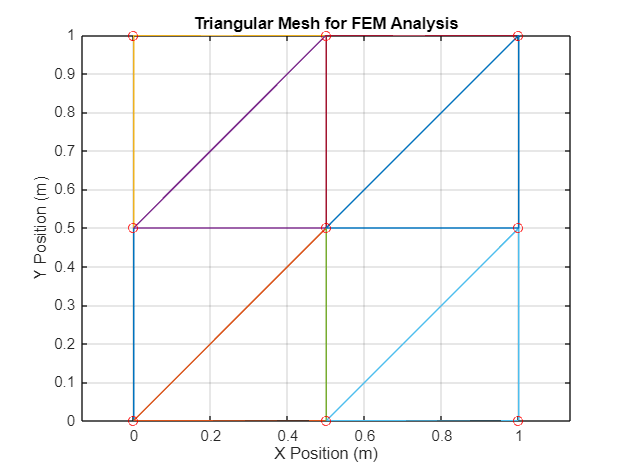

% Parameters
k = 50;              % Thermal conductivity (W/m.K)
Q = 1000;            % Heat source (W/m^2)
T_fixed = 25;        % Boundary temperature (°C)
Nx = 2;              % Number of elements along x (2squares → ~8 triangles)
Ny = 2;              % Number of elements along y

% Generate grid
L = 1;
dx = L / Nx;
dy = L / Ny;
[x_grid, y_grid] = meshgrid(0:dx:L, 0:dy:L);
nodes = [x_grid(:), y_grid(:)];
n_nodes = size(nodes,1);

% Create elements (split each square into 2 triangles)
elements = [];
for j = 1:Ny
    for i = 1:Nx
        % Node indices
        n1 = i + (j-1)*(Nx+1);
        n2 = n1 + 1;
        n3 = n1 + (Nx+1);
        n4 = n3 + 1;

        % Two triangles per square
        elements = [elements;
                    n1 n2 n4;
                    n1 n4 n3];
    end
end

%% Plot the mesh
figure;
trimesh(elements, nodes(:,1), nodes(:,2), 'LineWidth', 1);
title('Triangular Mesh for FEM Analysis');
xlabel('X Position (m)');
ylabel('Y Position (m)');
axis equal;
grid on;

%% Add annotations (optional)
hold on;
plot(nodes(:,1), nodes(:,2), 'ro', 'MarkerSize', 6); % Show nodes as red circles


% Print mesh statistics
fprintf('Mesh details:\n');

Mesh details:


fprintf('Number of nodes: %d\n', n_nodes);

Number of nodes: 9


fprintf('Number of elements: %d\n', size(elements,1));

Number of elements: 8





n_elements = size(elements,1);

% Initialize stiffness matrix and load vector
K = zeros(n_nodes);
F = zeros(n_nodes,1);

% Assemble global stiffness matrix
for e = 1:n_elements
    idx = elements(e,:);
    coords = nodes(idx,:);
    x = coords(:,1); y = coords(:,2);
    
    A = polyarea(x, y);
    b = [y(2)-y(3); y(3)-y(1); y(1)-y(2)];
    c = [x(3)-x(2); x(1)-x(3); x(2)-x(1)];
    
    ke = (k / (4*A)) * (b*b' + c*c');
    
    K(idx, idx) = K(idx, idx) + ke;
end

% Apply point heat source at center node
center_coord = [0.5, 0.5];
[~, center_node] = min(vecnorm(nodes - center_coord, 2, 2));
F(center_node) = Q;

% Apply boundary conditions
% Bottom edge: y = 0 → Dirichlet
tol = 1e-6;
fixed_nodes = find(abs(nodes(:,2)) < tol);
T = zeros(n_nodes, 1);
T(fixed_nodes) = T_fixed;
free_nodes = setdiff(1:n_nodes, fixed_nodes);

% Modify K and F for Dirichlet BC
F_mod = F(free_nodes) - K(free_nodes, fixed_nodes) * T(fixed_nodes);
K_mod = K(free_nodes, free_nodes);

% Solve
T(free_nodes) = K_mod \ F_mod;

%% Display results
disp('Nodal Temperatures:');

Nodal Temperatures:


for i = 1:n_nodes
    fprintf('Node %d (%0.1f, %0.1f): T = %.2f°C\n', i, nodes(i,1), nodes(i,2), T(i));
end

Node 1 (0.0, 0.0): T = 25.00°C
Node 2 (0.0, 0.5): T = 33.24°C
Node 3 (0.0, 1.0): T = 34.41°C
Node 4 (0.5, 0.0): T = 25.00°C
Node 5 (0.5, 0.5): T = 36.76°C
Node 6 (0.5, 1.0): T = 35.59°C
Node 7 (1.0, 0.0): T = 25.00°C
Node 8 (1.0, 0.5): T = 33.24°C
Node 9 (1.0, 1.0): T = 34.41°C


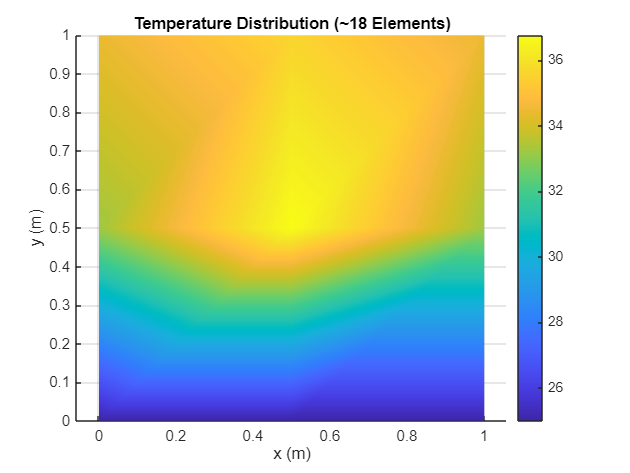


% Plotting
figure;
trisurf(elements, nodes(:,1), nodes(:,2), T, 'FaceColor','interp');
colorbar;
title('Temperature Distribution (~18 Elements)');
xlabel('x (m)'); ylabel('y (m)'); zlabel('Temperature (°C)');
view(2); axis equal; shading interp;

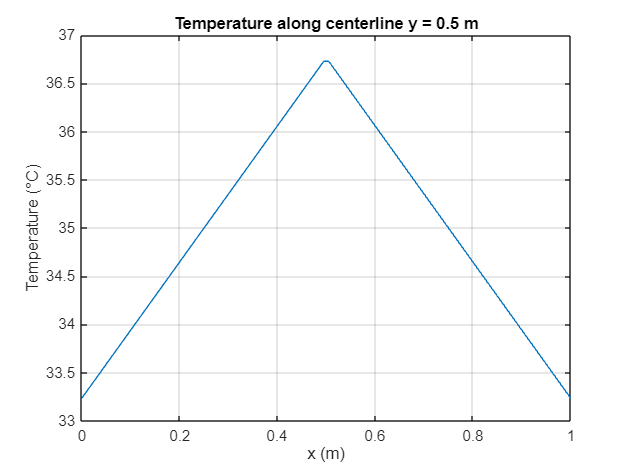


% Plot centerline (y = 0.5)
x_line = linspace(0, 1, 100);
T_line = griddata(nodes(:,1), nodes(:,2), T, x_line, 0.5*ones(size(x_line)));

figure;
plot(x_line, T_line, '-');
title('Temperature along centerline y = 0.5 m');
xlabel('x (m)'); ylabel('Temperature (°C)');
grid on;